# **Satellite Control Algorithm**

**Hongseok Kim**

##   I. Define Operational Mode

- Nadir Mode

- Sun Pointing Mode

- Ground Station Pointing Mode

- (Optional) B-dot control mode

##   II. Simulator by Step by Step

addpath('/Users/hongseokkim/Desktop/[Part2]SatelliteAttitudeControlEstimation/')


clear; clc;

Tsim = 1000;
delt = 1;
N = floor(Tsim/delt);
tVec = [0:N-1]' * delt;

% For Ground Station Pointing MOde
epoch = [2024*ones(N,1) 3*ones(N,1) 21*ones(N,1) floor(tVec/3600) rem(floor(tVec/60),60) rem(tVec,60)];
Austin_LLA = [30.285 -97.7335 70];
Austin_ECI = zeros(N,3);

for k = 1:N
Austin_ECI(k,:) = lla2eci(Austin_LLA,epoch(k,:));
end
Austin_ECI = Austin_ECI/1000;


% For Sun Pointing Mode
sun_vector = [1,0,0];

oversampFact = 10;

[r0,v0]=kepler2ijk_hs(7640,1.6e-5,100.7,90,0,0);

[t,y] = j2propagation_hs(r0,v0,tVec);

r = y(:,1:3);
v = y(:,4:6);

operation_mode = 2;
% 1: Nadir Pointing Mode
% 2: Ground Station (Austin) Pointing Mode
% 3 : Sun Pointing Mode


n = length(tVec);
xIstar = zeros(n,3);
yIstar = zeros(n,3);
zIstar = zeros(n,3);
e_star = zeros(n,3);

% NADIR Pointing Mode
if operation_mode == 1
    for i = 1:n
      zIstar(i,:) = -r(i,:)/norm(r(i,:));
      xIstar(i,:) = v(i,:)/norm(v(i,:));
      yIstar(i,:) = cross(zIstar(i,:),xIstar(i,:));
      
      %Generate Reference Euler Angle
          if cross( zIstar(i,:),xIstar(i,:))==0
          b_vec = cross(zIstar(i,:),xIstar(i,:));
          else
          b_vec = cross(zIstar(i,:),xIstar(i,:))/norm(cross(zIstar(i,:),xIstar(i,:))); 
          end
          a_vec = cross(b_vec,zIstar(i,:));
      R_BI_star_temp = [a_vec',b_vec',zIstar(i,:)']';
      e_star(i,:) = dcm2euler(R_BI_star_temp)';

    end
end


% Ground Station Contact Mode
slant_range = zeros(n,1);
if operation_mode == 2
    for i = 1:n
        zIstar(i,:) = (Austin_ECI(i,:) - r(i,:))/norm((Austin_ECI(i,:) - r(i,:)));
        slant_range(i) = norm(Austin_ECI(i,:) - r(i,:));
        yIstar(i,:) = cross(zIstar(i,:),v(i,:))/norm( cross(zIstar(i,:),v(i,:)));
        xIstar(i,:) = cross(yIstar(i,:),zIstar(i,:));

     %Generate Reference Euler Angle
          if cross( zIstar(i,:),xIstar(i,:))==0
          b_vec = cross(zIstar(i,:),xIstar(i,:));
          else
          b_vec = cross(zIstar(i,:),xIstar(i,:))/norm(cross(zIstar(i,:),xIstar(i,:))); 
          end
          a_vec = cross(b_vec,zIstar(i,:));
      R_BI_star_temp = [a_vec',b_vec',zIstar(i,:)']';
      e_star(i,:) = dcm2euler(R_BI_star_temp)';

    end
end


% Sun Pointing Mode
if operation_mode == 3
    for i = 1:n
       yIstar(i,:) = -sun_vector;
       zIstar(i,:) = cross(v(i,:),yIstar(i,:))/norm( cross(v(i,:),yIstar(i,:)));
       xIstar(i,:) = cross(yIstar(i,:),zIstar(i,:));


     %Generate Reference Euler Angle
          if cross( zIstar(i,:),xIstar(i,:))==0
          b_vec = cross(zIstar(i,:),xIstar(i,:));
          else
          b_vec = cross(zIstar(i,:),xIstar(i,:))/norm(cross(zIstar(i,:),xIstar(i,:))); 
          end
          a_vec = cross(b_vec,zIstar(i,:));
      R_BI_star_temp = [a_vec',b_vec',zIstar(i,:)']';
      e_star(i,:) = dcm2euler(R_BI_star_temp)';

    end
end


% x_I_star_0 = xIstar(1,:)';
% z_I_star_0 = zIstar(1,:)';

z_I_star_0 =  -(r(1,:)/norm(r(1,:)))';
x_I_star_0 = (v(1,:)/norm(v(1,:)))';

e_star = zeros(n,3);

for i = 1:n

if cross(zIstar(i,:),xIstar(i,:)) == 0
    bi = cross(zIstar(i,:) ,xIstar(i,:))';
else
    bi = cross(zIstar(i,:),xIstar(i,:))'/norm(cross(zIstar(i,:),xIstar(i,:)));
end
  ai = cross(bi,zIstar(i,:)');
  R_BI_temp = [ai,bi,zIstar(i,:)']';
  e_star(i,:) = dcm2euler(R_BI_temp)';
end


if cross(z_I_star_0,x_I_star_0) == 0
    b = cross(z_I_star_0 ,x_I_star_0);
else
    b = cross(z_I_star_0,x_I_star_0)/norm(cross(z_I_star_0,x_I_star_0));
end

a = cross(b,z_I_star_0);

R_BI_0 = [a,b,z_I_star_0]';
e0 = dcm2euler(R_BI_0);
R_BI_ref = euler2dcm(e0);

R.tVec = tVec;
R.xIstar = xIstar;
R.zIstar = zIstar;

S.oversampFact = oversampFact;
S.state0.r = r0;
S.state0.v = v0;
S.state0.e = e0;
S.state0.omegaB = zeros(3,1);
S.distMat = zeros(N-1,3);

quadParamsScript;
constantsScript;
P.quadParams = quadParams;
P.constants = constants;
% Run Satellite Control Simulator
Q = simulateSATControl(R,S,P);



## III. Output Generation

### III.1 Satellite Trajectory with Body Axis Vector Display

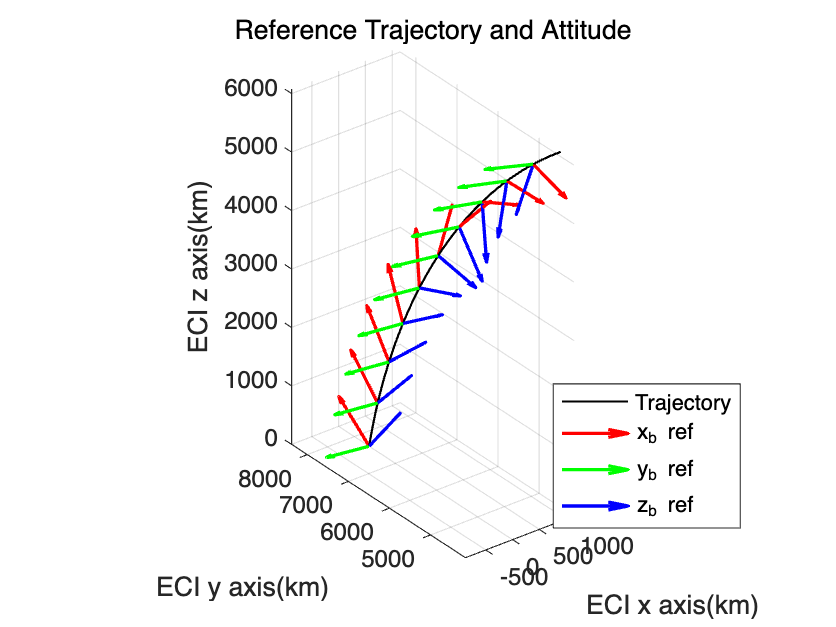

% Reference Trajectory and Attitude

figure;

plot3(r(:,1), r(:,2), r(:,3),'Color','k','LineWidth',1)
hold on;
grid on;
axis equal;
title('Reference Trajectory and Attitude')
xlabel('ECI x axis(km)')
ylabel('ECI y axis(km)')
zlabel('ECI z axis(km)')

hold on
scalefactor = 1000;
xdir = scalefactor * xIstar;
ydir = scalefactor * yIstar;
zdir = scalefactor * zIstar;
arrowLineWidth = 1.5;



for i = 1:100:length(tVec)
  startPos = r(i,1:3);

  quiver3(startPos(1), startPos(2), startPos(3),xdir(i,1),xdir(i,2),xdir(i,3),...
      'Color', 'r', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),ydir(i,1),ydir(i,2),ydir(i,3),...
      'Color', 'g', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),zdir(i,1),zdir(i,2),zdir(i,3),...
      'Color', 'b', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
end

hold off;
legend('Trajectory','x_b ref','y_b ref','z_b ref')

legend("Position", [0.17506,0.13938,0.15179,0.15595])

legend("Position", [0.69763,0.19517,0.15179,0.15595])

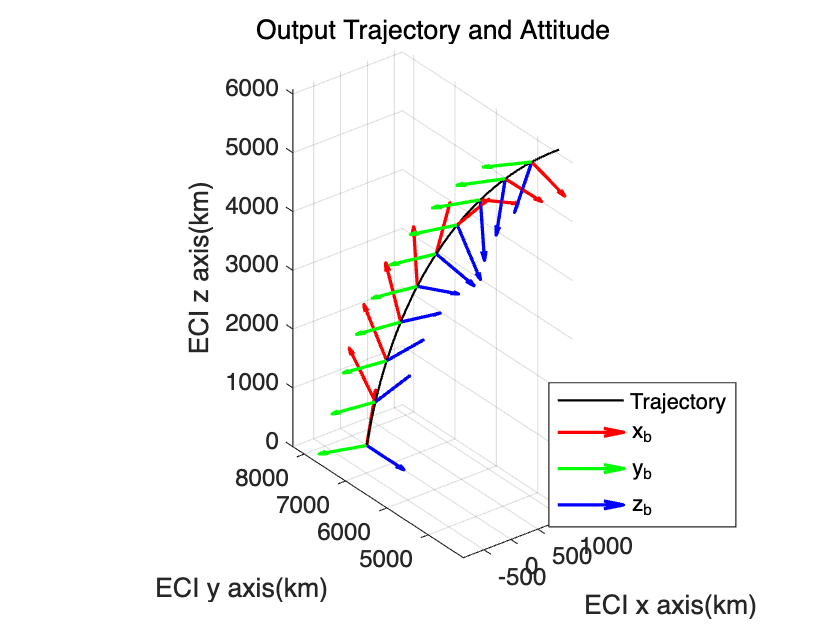



% Output Trajectory and Attitude

figure;

plot3(Q.state.rMat(:,1), Q.state.rMat(:,2), Q.state.rMat(:,3),'Color','k','LineWidth',1)
hold on;
grid on;
axis equal;
title('Output Trajectory and Attitude')
xlabel('ECI x axis(km)')
ylabel('ECI y axis(km)')
zlabel('ECI z axis(km)')

hold on
scalefactor = 1000;
xdir = scalefactor * Q.state.xIMat;
ydir = scalefactor * Q.state.yIMat;
zdir = scalefactor * Q.state.zIMat;
arrowLineWidth = 1.5;



for i = 1:1000:length(Q.tVec)
  startPos = Q.state.rMat(i,1:3);

  quiver3(startPos(1), startPos(2), startPos(3),xdir(i,1),xdir(i,2),xdir(i,3),...
      'Color', 'r', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),ydir(i,1),ydir(i,2),ydir(i,3),...
      'Color', 'g', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),zdir(i,1),zdir(i,2),zdir(i,3),...
      'Color', 'b', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
end

hold off;
legend('Trajectory','x_b','y_b','z_b')

legend("Position", [0.18054,0.12217,0.15179,0.15595])

legend("Position", [0.6927,0.19606,0.15179,0.15595])

## III.1.1 Body Axis Vector Comparison

Nadir Mode: z axis compare

GS contact Mode: z axis compare

Sun Pointing Mode: y axis compare

## III.2 Satellite Euler Angle (Roll, Pitch, Yaw) display

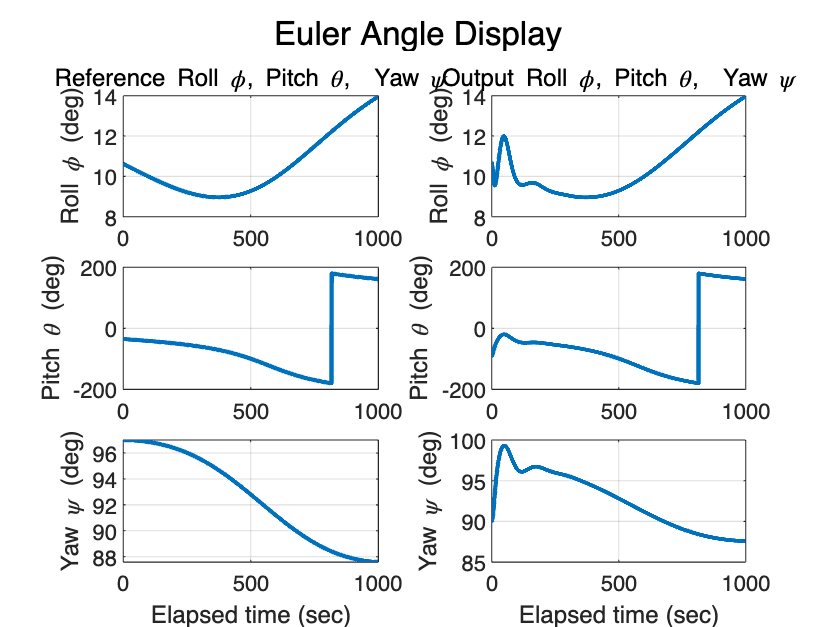

figure;
sgtitle('Euler Angle Display')


subplot(3,2,1)
plot(tVec,e_star(:,1)/pi*180,'LineWidth',2)
ylabel('Roll \phi (deg)')
title('Reference Roll \phi, Pitch \theta,  Yaw \psi')
grid on

subplot(3,2,2)
plot(Q.tVec,Q.state.eMat(:,1)/pi*180,'LineWidth',2)
ylabel('Roll \phi (deg)')
title('Output Roll \phi, Pitch \theta,  Yaw \psi')
grid on


subplot(3,2,3)
plot(tVec,e_star(:,2)/pi*180,'LineWidth',2)
ylabel('Pitch \theta (deg)')
grid on

subplot(3,2,4)
plot(Q.tVec,Q.state.eMat(:,2)/pi*180,'LineWidth',2)
ylabel('Pitch \theta (deg)')
grid on

subplot(3,2,5)
plot(tVec,e_star(:,3)/pi*180,'LineWidth',2)
xlabel('Elapsed time (sec)')
ylabel('Yaw \psi (deg)')
grid on

subplot(3,2,6)
plot(Q.tVec,Q.state.eMat(:,3)/pi*180,'LineWidth',2)
xlabel('Elapsed time (sec)')
ylabel('Yaw \psi (deg)')
grid on

### III.3 Reaction Wheel Angular Rate Display

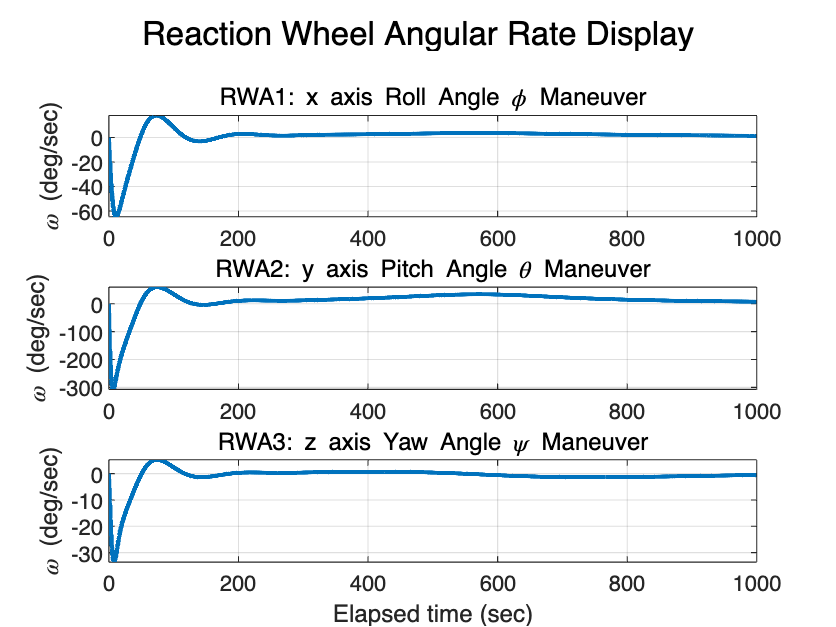

figure;
sgtitle('Reaction Wheel Angular Rate Display')

subplot(3,1,1)
plot(Q.tVec,Q.state.omegaVecMat(:,1)/pi*180,'LineWidth',2)
title('RWA1: x axis Roll Angle \phi Maneuver')
ylabel('\omega (deg/sec)')
grid on

subplot(3,1,2)
plot(Q.tVec,Q.state.omegaVecMat(:,2)/pi*180,'LineWidth',2)
title('RWA2: y axis Pitch Angle \theta Maneuver')
ylabel('\omega (deg/sec)')
grid on

subplot(3,1,3)
plot(Q.tVec,Q.state.omegaVecMat(:,3)/pi*180,'LineWidth',2)
title('RWA3: z axis Yaw Angle \psi Maneuver')
ylabel('\omega (deg/sec)')
xlabel('Elapsed time (sec)')
grid on

### III.4 Slant Range (Satellite to Austin)

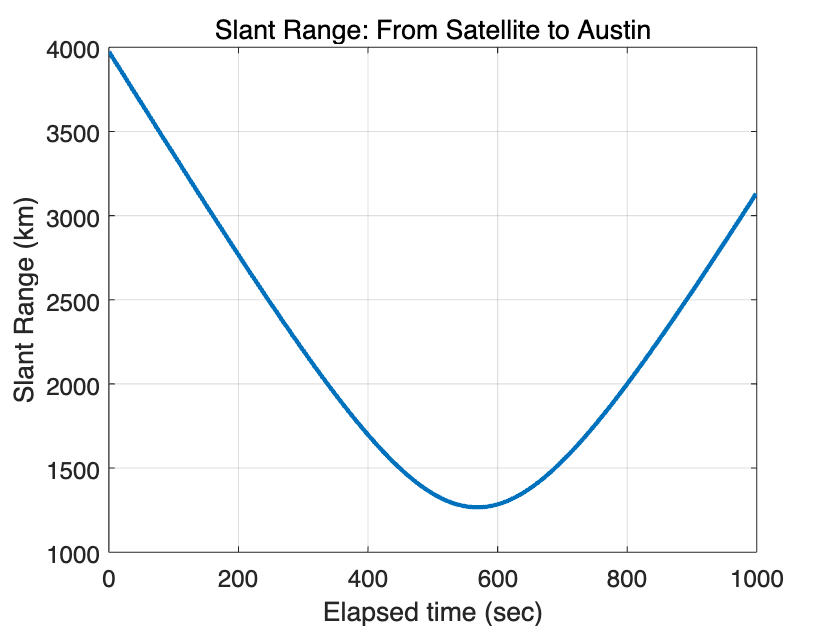

figure;
plot(tVec,slant_range,'LineWidth',2)
title('Slant Range: From Satellite to Austin')
xlabel('Elapsed time (sec)')
ylabel('Slant Range (km)')
grid on